# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 13-Dec-2022 14:50:21

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["VarName1", "lat", "lon", "alt", "mlat", "cr", "time"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore"; 
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "time", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "time", "EmptyFieldRule", "auto");

% Import the data
filtereddf = readtable("/Home/siv30/wad005/master/GRB/MATLAB/david_sarria/filtered_df.csv", opts)

## Clear temporary variables

clear opts

% scatter(filtereddf.mlat,filtereddf.cr)
% 
% P = [filtereddf.mlat,filtereddf.cr];
% [k,av] = convhull(P,'Simplify',true);
% plot(P(:,1),P(:,2),'*')
% hold on
% plot(P(k,1),P(k,2))
% hold off

% scatter(filtereddf.mlat,filtereddf.cr);
% hold on
% coefs = polyfit(P(:,1),P(:,2),2);
% x = linspace(-60,60,100);
% y = polyval(coefs,x);
% plot(x,y)
% hold off

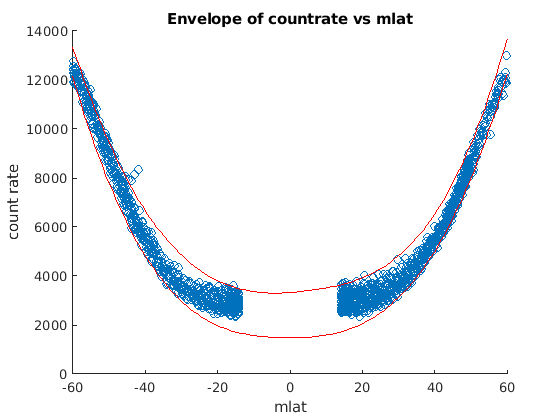

x = linspace(-60,60,120); % define the x-axis values
scatter(filtereddf.mlat,filtereddf.cr);
hold on
coefs = polyfit(P(:,1),P(:,2),5);
y = polyval(coefs,x);
noise = 950; % define the noise level (adjust as needed)
y = y + noise * sin(x); % add sinusoidal noise to y

% compute the envelope of y
[lower,upper] = envelope(y,24,'peak');

% plot the envelope of y
plot(x, lower, 'color', 'red');
plot(x, upper, 'color', 'red');

% add labels to the plot
xlabel('mlat');
ylabel('count rate');
title('Envelope of countrate vs mlat');

hold off